# Computer Vision Lab 3

# Feature detection and matching

**Authors**: Emer Rodriguez Formisano and Jorge Alexander  

**Date**: 24/10/2017

## 1. Introduction

run('vlfeat-0.9.16/toolbox/vl_setup');
vl_version

0.9.16


## 2. Feature detection

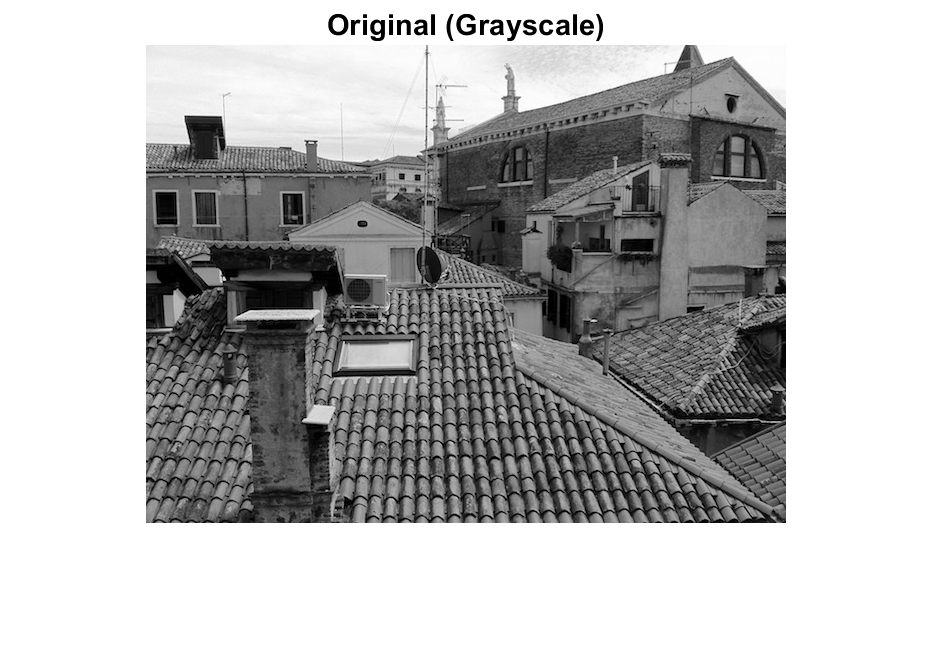

I = vl_impattern('roofs1');
I = single(rgb2gray(I));
imshow(I), title('Original (Grayscale)');

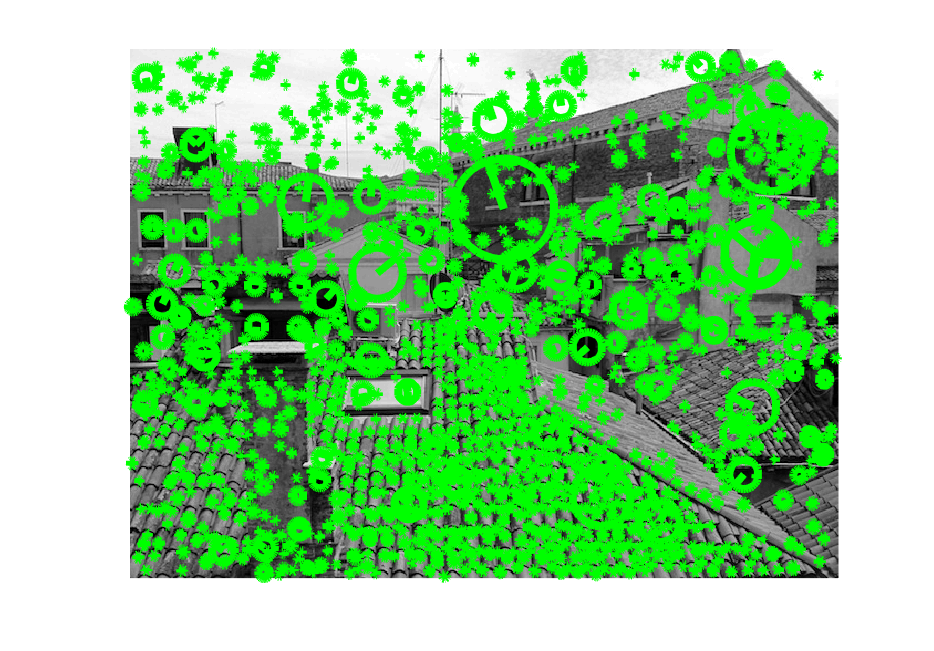

[f, d] = vl_sift(I);
show_keypoints(I, f);

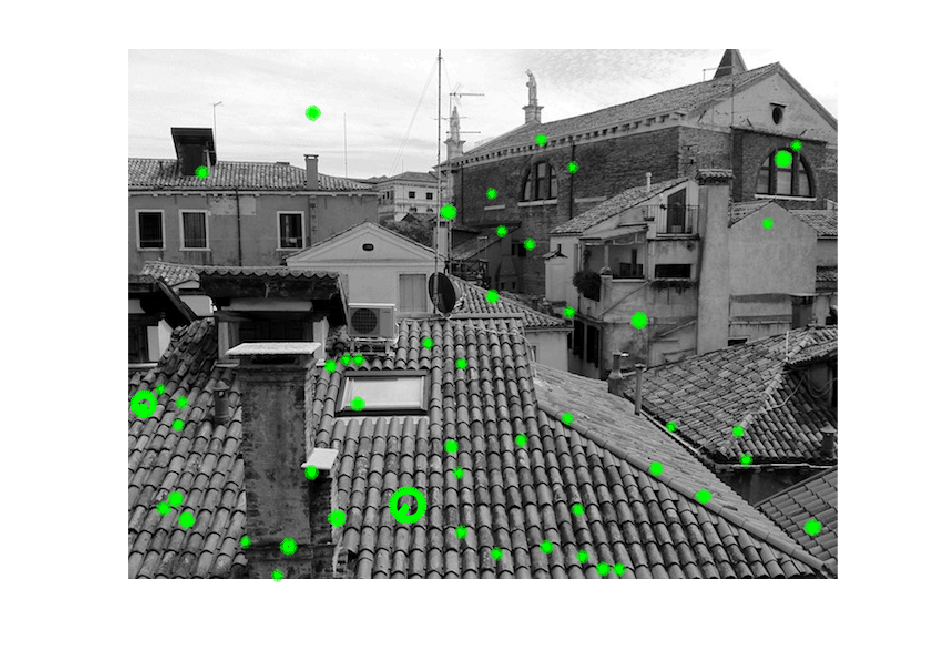

show_keypoints(I,random_selection(f,50))

**Question 1**: Take at your own choice several keypoints that have been detected at di�erent scales. Using the theory given in the lectures, comment on the reasons of why do you think that a keypoint has been detected at that position and at that particular scale. You may repeat the experiment with another image (such as 'river1') to understand what a signi�cant keypoints is.

ANSWER + IMAGES

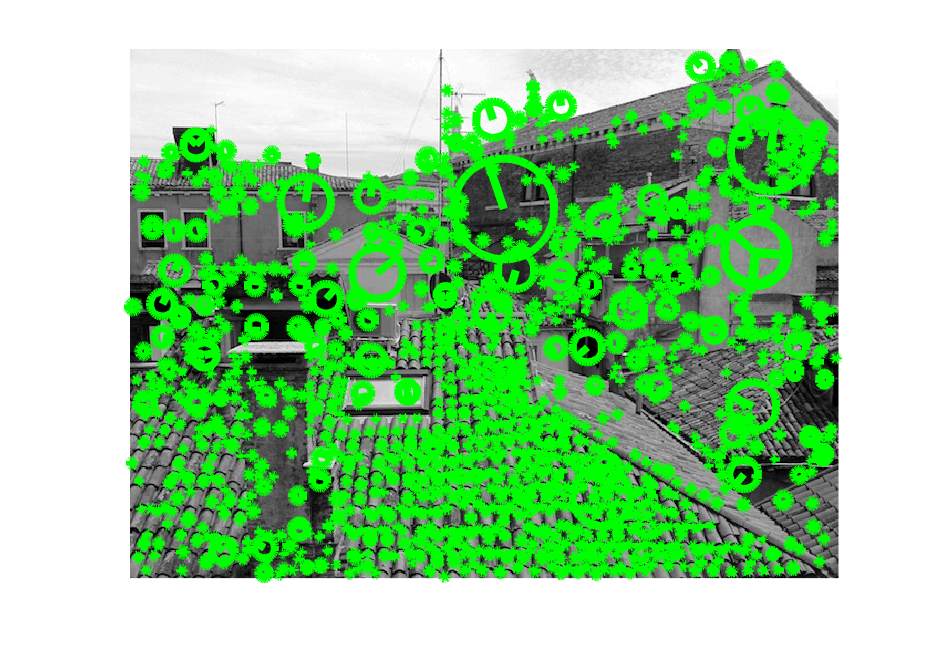

[f, d] = vl_sift(I, 'PeakThresh', 0.01);
show_keypoints(I, f);